依赖[统一实验分析作图v20.3.0](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases/)

饼图，显示声转光的Learned和Transfer命中率

MOpBaseline=TransferLearning.MOpBaseline;

CalciumBehavior=structfun(@(T)height(unique(T)),MOpBaseline.TableQuery("TrialUID",UniExp.ReadQueryTable(TransferLearning.ProjectPath('查询表.xlsx'),'Fig1K')),UniformOutput=false);

figure;
Layout=tiledlayout(1,2,TileSpacing='none',Padding='tight');
MATLAB.Graphics.NestedPie({[CalciumBehavior.Learned_hit,CalciumBehavior.Learned_miss]},AxesHandle=nexttile);

MATLAB.Graphics.NestedPie({[CalciumBehavior.Transfer_hit,CalciumBehavior.Transfer_miss]},AxesHandle=nexttile);

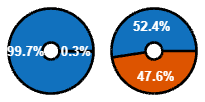

MATLAB.Graphics.FigureAspectRatio(2,1,1/3);
print(TransferLearning.ProjectPath('Fig1K.svg'),'-dsvg');